% 重新训练神经网络
% 通常情况下，每个反向传播训练会话都从不同的初始权重和偏置开始，
% 并以不同方式将数据划分为训练集、验证集和测试集。
% 对于同一个问题，这些不同条件会导致相差很大的解。
% 
% 最好训练几个网络，以确保找到具有良好泛化能力的网络。

## 留出法

在此处，加载数据集并将其划分为两部分：90% 用于设计网络，10% 用于测试所有网络。

[x, t] = bodyfat_dataset;
Q = size(x, 2);
Q1 = floor(Q * 0.90);
Q2 = Q - Q1;
ind = randperm(Q);
ind1 = ind(1:Q1);
ind2 = ind(Q1 + (1:Q2));
x1 = x(:, ind1);
t1 = t(:, ind1);
x2 = x(:, ind2);
t2 = t(:, ind2);

## 十次训练

接下来，选择一种网络架构并基于数据集的第一部分进行十次训练，并求出各网络架构在数据集第二部分上的均方误差。

Training 1/10
Training 2/10
Training 3/10
Training 4/10
Training 5/10
Training 6/10
Training 7/10
Training 8/10
Training 9/10
Training 10/10


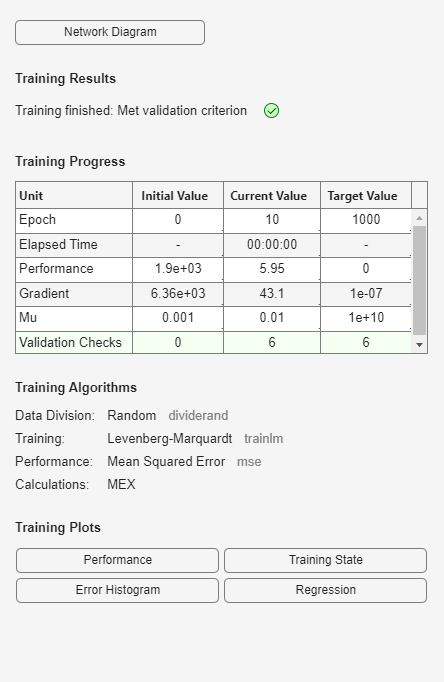

net = feedforwardnet(10);
numNN = 10;
NN = cell(1, numNN);
perfs = zeros(1, numNN);
for i = 1:numNN
  fprintf('Training %d/%d\n', i, numNN);
  NN{i} = train(net, x1, t1);
  y2 = NN{i}(x2);
  perfs(i) = mse(net, t2, y2);
end

% 每个网络都将从不同初始权重和偏置开始进行训练，
% 并将第一个数据集以不同比例划分为训练集、验证集和测试集。
% 请注意，测试集适合度量每个对应网络的泛化能力，但不适合所有网络，
% 因为作为一个网络的测试集的数据可能会被其他神经网络用于训练或验证。
% 这也是为什么原始数据集被划分为两部分，这是为了确保保留完全独立的测试集。

% 性能最差的神经网络是泛化用于数据集第二部分时效果最佳的网络。